%CIFAR10
rootFolder = 'cifar10Train';
categories = {'airplane','automobile','bird','cat','deer','dog','frog','horse','ship','truck'};

%CIFAR100
% rootFolder = 'cifar100Train';
% categories = {'keyboard', 'tulip', 'oak_tree', 'turtle', 'mountain', 'pickup_truck', 'clock', 'otter', 'whale', 'lawn_mower', 'girl', 'sunflower', 'elephant', 'tiger', 'plate', 'crocodile', 'butterfly', 'hamster', 'tank', 'orchid', 'snake', 'squirrel', 'lion', 'camel', 'bottle', 'lizard', 'bee', 'maple_tree', 'shark', 'mushroom', 'television', 'rabbit', 'sea', 'house', 'streetcar', 'couch', 'skyscraper', 'shrew', 'beetle', 'pine_tree', 'aquarium_fish', 'leopard', 'lobster', 'telephone', 'raccoon', 'road', 'cattle', 'cloud', 'kangaroo', 'crab', 'castle', 'lamp', 'man', 'bed', 'forest', 'poppy', 'dolphin', 'rocket', 'orange', 'mouse', 'flatfish', 'sweet_pepper', 'baby', 'pear', 'skunk', 'wardrobe', 'porcupine', 'bridge', 'chair', 'can', 'cockroach', 'wolf', 'willow_tree', 'motorcycle', 'snail', 'plain', 'tractor', 'seal', 'trout', 'palm_tree', 'possum', 'worm', 'cup', 'dinosaur', 'fox', 'ray', 'rose', 'bicycle', 'bus', 'table', 'caterpillar', 'boy', 'chimpanzee', 'train', 'bowl', 'woman', 'beaver', 'spider', 'apple', 'bear'};

%COREL80
% rootFolder = 'CorelDB';
% categories = {'art_dino', 'bld_sculpt', 'obj_aviation', 'obj_car', 'obj_door', 'obj_moleculr', 'pet_cat', 'sc_', 'sc_iceburg', 'sc_rural', 'texture_1', 'texture_6', 'wl_eagle', 'wl_horse', 'wl_owls', 'wl_wolf', 'art_mural', 'eat_drinks', 'obj_balloon', 'obj_cards', 'obj_eastregg', 'obj_orbits', 'pet_dog', 'sc_autumn', 'sc_indoor', 'sc_sunset', 'texture_2', 'wl_buttrfly', 'wl_elephant', 'wl_lepoad', 'wl_porp', 'woman', 'art_1', 'bld_castle', 'eat_feasts', 'obj_bob', 'obj_decoys', 'obj_flags', 'obj_ship', 'pl_flower', 'sc_cloud', 'sc_mountain', 'sc_waterfal', 'texture_3', 'wl_cat', 'wl_fish', 'wl_lion', 'wl_primates', 'art_antiques', 'bld_lighthse', 'fitness', 'obj_bonsai', 'obj_dish', 'obj_mask', 'obj_steameng', 'pl_foliage', 'sc_firewrk', 'sc_night', 'sc_waves', 'texture_4', 'wl_cougr', 'wl_fox', 'wl_lizard', 'wl_roho', 'art_cybr', 'bld_modern', 'obj_234000', 'obj_bus', 'obj_doll', 'obj_mineral', 'obj_train', 'pl_mashroom', 'sc_forests', 'sc_rockform', 'sp_ski', 'texture_5', 'wl_deer', 'wl_goat', 'wl_nests', 'wl_tiger'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imagesPerClass = 100;
[trainingSet, testingSet] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
    % I = imresize(I, [256 256]); % can try with this
    sift = detectSIFTFeatures(I).selectStrongest(25);
    [features, sift_points] = extractFeatures(I, sift);
    featureSet = cat(2, featureSet, features.');
    ref = cat(2, ref, repmat([i], 1, size(features,1)));
end


% construct LSH hash tables for featureSet
cd('vLSH')

% Tune hyperparameters
K = 32;   % # of nearest neighbors to search for each query
L = 10;   % # of tables
M = 25;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);

Creating table 1/10
	Projecting data...
	12695 buckets
	min / max size: 1 / 10
	mean / median: 1.040331e+00 / 1
Creating table 2/10
	Projecting data...
	12810 buckets
	min / max size: 1 / 7
	mean / median: 1.030991e+00 / 1
Creating table 3/10
	Projecting data...
	12752 buckets
	min / max size: 1 / 7
	mean / median: 1.035681e+00 / 1
Creating table 4/10
	Projecting data...
	12958 buckets
	min / max size: 1 / 7
	mean / median: 1.019216e+00 / 1
Creating table 5/10
	Projecting data...
	12454 buckets
	min / max size: 1 / 8
	mean / median: 1.060463e+00 / 1
Creating table 6/10
	Projecting data...
	12685 buckets
	min / max size: 1 / 7
	mean / median: 1.041151e+00 / 1
Creating table 7/10
	Projecting data...
	12596 buckets
	min / max size: 1 / 7
	mean / median: 1.048507e+00 / 1
Creating table 8/10
	Projecting data...
	12612 buckets
	min / max size: 1 / 6
	mean / median: 1.047177e+00 / 1
Creating table 9/10
	Projecting data...
	12375 buckets
	min / max size: 1 / 11
	mean / median: 1.067232e+00 / 1

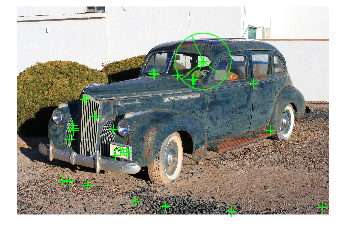

% query an input image
I = imread("car1.jpg");
% I = imresize(I, [256 256]); % can try with this
figure, imshow(I); hold on;
I = im2gray(I);
sift = detectSIFTFeatures(I).selectStrongest(25);
[queryFeatures, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);


[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(queryFeatures.', featureSet, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.143558 seconds
Retrieving candidates from table 2
	-----> 0.134478 seconds
Retrieving candidates from table 3
	-----> 0.120343 seconds
Retrieving candidates from table 4
	-----> 0.106747 seconds
Retrieving candidates from table 5
	-----> 0.127592 seconds
Retrieving candidates from table 6
	-----> 0.111035 seconds
Retrieving candidates from table 7
	-----> 0.114435 seconds
Retrieving candidates from table 8
	-----> 0.110895 seconds
Retrieving candidates from table 9
	-----> 0.102824 seconds
Retrieving candidates from table 10
	-----> 0.097405 seconds
Removing duplicate candidates...
	-----> 0.004934 seconds
Performing knn search...
	-----> 0.003324 seconds
Calculating candidate sizes...
	-----> 0.052449 seconds


% convert the feature IDs into their original image IDs
oriImages = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          oriImages(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(oriImages);
N = numel(uniqImageIds);
weights = zeros(N,1);

for k = 1 : N % unranked weighting of NNs
    weights(k) = sum(sum(oriImages == uniqImageIds(k))); 
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');


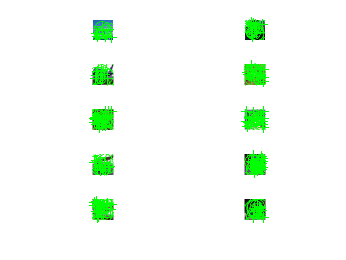

% display top 20 the matching images
figure;
offset = 0;
for pic = 1 : min(11, length(ranks))
    if pic - offset > 10
        break;
    end
    if ranks(pic,2) == 0
        offset = 1;
    end
    if ranks(pic,2)>0
        % plot original image
        I = readimage(trainingSet, ranks(pic, 2));
        subplot(5,2,pic - offset), imshow(I); hold on
        I = im2gray(I);
        sift = detectSIFTFeatures(I).selectStrongest(25);
        [queryFeatures, valid_points] = extractFeatures(I, sift);
        plot(valid_points,'showOrientation',true);
    end
end

cd('..')